# Geostatistika Lekce 2

## Otázky

- Ve vzorci v knize 2.4 a 2.5 (již před 2.4) používáte index $i$ a $j$. Pokud jsem to správně pochopil, procházejí tyto indexy přes sousední prvky. Je nutné je potom rozlišovat? Zkusil jsem si vzorce cvičně přepsat (snad bez mnoha chyb) a po svém upravit, abych nakonec došel ke tvarům, které uvádíte v knize, ale použil jsem jen jeden index.

- Pokud to vyhovuje, budu vkládat některé přepsané kódy přímo do tohoto dokumentu, abych nemusel přikládat matlabovský soubor kvůli omezení SIS.

- Je nějaká konvence pro odsazování a komentování MATLAB funkcí případně skriptů? Po troše hledání se mi zdá, že to není nikde zcela jasně popsané.

# Lineární interpolace

Mějme naměřené hodnoty $z1$ a $z2$ v bodech $x1$ a $x2$. Hledáme neznámou hodnotu v bodě $z_0$, který leží mezi oběma danými body. Pro odhad hodnoty můžeme použít lineární interpolaci, kdy předpokládáme, že hledaná hodnota leží na spojnici (přímce) mezi body $z_1$ a $z2$. 

**Odvodíme** lineární závislost, do které poté můžeme dosadit  hodnotu $x_0$ z podobnosti trojúhelníků, Pro směrnici přímky platí, že $k = \frac{z_2 - z_1}{x_2 - x_1}$ a zároveň $k =  \frac{z - z_1}{x - x_1}$. Nakonec vyjádřením dostaneme $z = z_1 + \frac{z_2 - z_1}{x_2 - x_1} (x -  x_1)$. 

### Lineární interpolace v jednom bodě

Programový kód pro lineární interpolaci v jednom zadaném bodě je uložen v souboru `linearInterpolation1.m` s následujícím obsahem.

**Úkol 1**.    Do dokumentu vložte právě vytvořený obrázek interpolace

**Úkol 2.    **Projděte si kód a pokuste se porozumnět jednotlivým příkazům. Kde to pokládáte za vhodné, vložte vysvětlující kometáře (začínají znakem %).

**Příklad 1.    **Ve dvou bodech na ose $x$ o souřadnicích $x_1 = 1$ a $x2 = 3$ byly naměřeny hodnoty $z_1 = 10$ a $z_2 = 20$. Pomocí lineární interpolace najděte hodnotu $z_0$ v bodě $x_0 = 1.5$.

x1 = 1.0; z1 = 10.0;
x2 = 3.0; z2 = 20.0;
x0 = 1.5; z0 = linearInterpolation1(x1, z1, x2, z2, x0);

fprintf('%f', z0);

12.500000

Hodnoty si můžeme vykreslit do grafu, kde hledaný bod je červeně.

axis([0, 5, 0, 25]);
axis padded;
plot(x1, z1, 'bo', x2, z2, 'bo', x0, z0, 'ro', 'MarkerSize', 8);
grid on;

### Lineární interpolace ve více bodech

Programový kód pro lineární interpolace v $N$ bodech je uložen v souboru `linearInterpolationN.m` s následujícím obsahem.

Vykreslíme si postupné interpolování pro jednotlivé body v poli `xs` a `zs`.

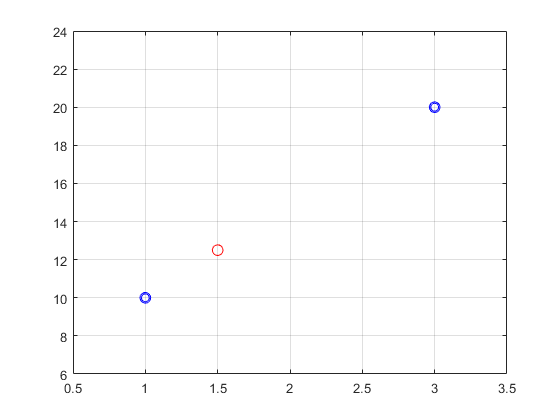

xs = [0.5: 0.1 :3.5];
zs = linearInterpolationN(x1, z1, x2, z2, xs);

hold on; % Nastavení překreslování grafu.
plot(x1, z1,'bo');
plot(x2, z2,'bo');
for i = 1 : length(zs)
    plot(xs(i), zs(i),'b--');
    pause(0.1) % Nastavení zdržení animace v sekundách.
end

grid on;
hold off % Zruš nastavení, jinak platí pro další vyhodnocení buňky.

# Metoda IDW

(učebnice GPI na str. 17 až 23)

Metoda *Inverse Distance Weighting *(IDW) neboli *metoda inverzních vzdáleností *je založena na prostorová interpolační metoda založená na stanovení hodnoty hledaného bodu pomocí váženého průměru vzdálenosti okolních bodů.

## **Odvození**

Mějme bod $Z_0$ jehož hodnotu $z_0^*$ chceme odhadnout (hvezdička značí odhad) a v jeho okolí body $Z_i$ o známých hodnotách $z_i$ (GPI obr. 2.1).  


$$z_0^* = \sum_{i=1}^n \lambda_i z_i$$


Pokud hodnota všech bodů v okolí stejná tj. $z_i = z$, požadujeme, aby odhadnutá hodnota byla také stejná tj. $z_0 = z$.


$$z = z_0^* := \sum_{i=1}^n \lambda_i z_i = z  \sum \lambda_i  = z  \lambda

$$



$$\therefore \lambda = \frac{z}{z} = 1$$


Požadavek aby součet vah $\lambda$ byl roven jedné budeme nazývat jako normovací podmínku.

Jednotlivé váhy pak položíme jako


$$\lambda_i = \frac{c}{r_i^{\alpha}} = c r_i^{-\alpha},$$


kde $r_i$ je vzdálenost $i$-tého bodu $Z_i$ od bodu $Z_0$, mocnina $\alpha \gt  0$ a $c$ je *škálovací koeficient, *odvodíme z normovací podmínky


$$\sum \lambda_i = \sum c  r_i^{-\alpha} = c \sum r_i^{-\alpha}  = 1 \therefore$$



$$c = \frac{1} {\sum r_i^{-\alpha}}$$


potom pro váhy dostaneme


$$\lambda_i = \frac{r_i^{-\alpha}}{\sum r_i^{-\alpha} } $$


(GPI 2.4)

a dosazením do získáme výdledný vzorec


$$z_0^*  = \frac{\sum r_i^{-\alpha}z_i }{\sum r_i^{-\alpha}} = \frac{\sum \frac{z_i}{r_i^{\alpha}}}{\sum \frac{1}{r_i^{\alpha}}}$$
 

(GPI 2.5)

Vetšinou první počítáme váhy, protože můžeme výpočet vah porovnávat s dosaženým výsledkem pro různě volené mocniny $\alpha$.

## Vlastnosti

- Charakteristickou vlastností IDW je tendence k průměru.

- Jde o přesnou interpolační metody tzn. že plocha prochází datovými body.

- Extrémní hodnoty tj. maxima a minima plochy jsou v datových bodech.

- Pokud se pohybujeme uvnitř intervalu lze lineární interpolaci chápat jako speciální případ IDW s hodnotou $\alpha = 1$ (IDW1), to však již neplatí vně intervalu! Pro $\alpha \neq 1$ shoda LI s IDW již neplatí, např. pro $\alpha = 10$ (IDW10) již dostáváme výsledky podobné jako při metodě nebližšího souseda (*nearest neighbors method).*

**Příklad 2.    **Ve dvou bodech na ose $x$ o souřadnicích $x_1=0.5$ = 1 a $x_2 = 3$byly naměřeny hodnoty $z_1 = 10$ a $z_2 = 20$. Pomocí interpolace metodou IDW s koeficientem (mocninou) $\alpha = 1$ najděte hodnotu veličiny $z_0$ v bodě $x_0$ = 1.5.

**Úkol 3.    **Načrtněte situaci (tužka-papír) a zkuste nejprve přijít na řešení bez následujícího návodu .  

**Řešení    **Zjistím sumu převrácených hodnot jednotlivých vdáleností $R = \sum 1/r_i^{\alpha = 1}$ a spočtem jednotlivé normalizované váhy $\lambda_i = \frac{1}{r_i R}$,vyjde nám 

x1 = 0.5;
z1 = 10.0;
x2 = 3.0;
z2 = 20.0;
x0 = 1.5;

r1 = abs(x0 - x1);
r2 = abs(x0 - x2);

R  = (1/r1) + (1/r2);

l1 = (1/r1)/R;
l2 = (1/r2)/R;

assert(l1 + l2 == 1.0); % Součet vah musí být jedna.

z0  = l1 * z1 + l2 * z2;

plot([x1, x2], [z1, z2], 'r--', x0, z0, 'blacko');

**Úkol 4.** Vložte do dokumentu výsledný obrázek z funkce `intpol_IDW`a zkuste vysvětlit, proč se výsledky interpolace na krajích oblasti blíží průměru dat.

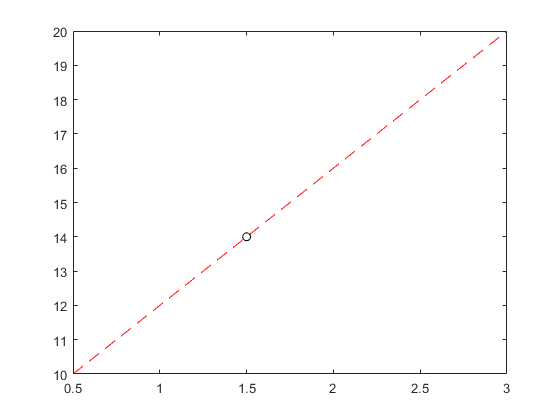

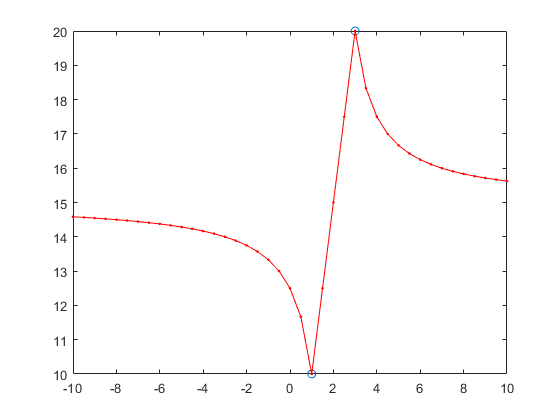

ans =    14.5833   14.5652   14.5455   14.5238   14.5000   14.4737   14.4444   14.4118   14.3750   14.3333   14.2857   14.2308   14.1667   14.0909   14.0000   13.8889   13.7500   13.5714   13.3333   13.0000   12.5000   11.6667   10.0000   12.5000   15.0000   17.5000   20.0000   18.3333   17.5000   17.0000   16.6667   16.4286   16.2500   16.1111   16.0000   15.9091   15.8333   15.7692   15.7143   15.6667   15.6250


intpol_IDW([1 3], [10 20], [-10:0.5:10], 1)

IDW je metoda, jejíž charakteristickou vlastností je tendence k průměru. Pro zadaný interval se k tomuto průmeru, pokud jsme vně, rychle blížíme, narozdíl např od lin. interpolace a jiných metod . Vysvělení tohoto chování je v GPI na straně 21.

**Poznámka: **Zkratka `NaN` znamená `NOT A NUMBER` a může se objevit např. při dělění nulou. 

**Úkol 5.** Napište, která volba mocniny se jeví jako nejvhodnější? Druhá mocnina se jeví vizuálně jako nejlepší.

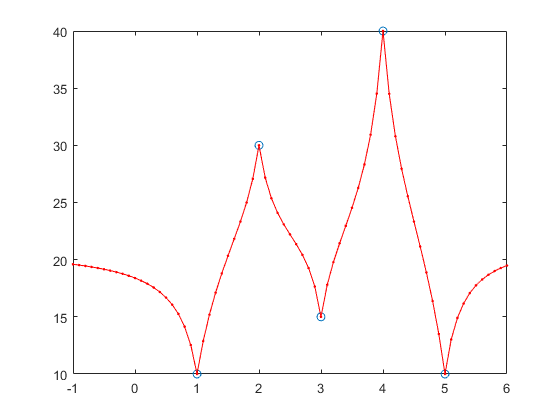

intpol_IDW([1 2 3 4 5],[10 30 15 40 10],[-1:0.1:6], 1);

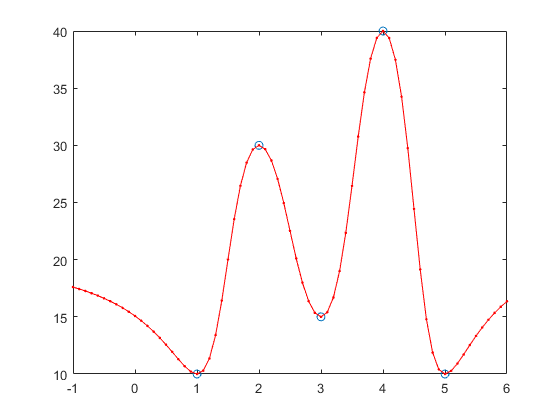

intpol_IDW([1 2 3 4 5],[10 30 15 40 10],[-1:0.1:6], 2);

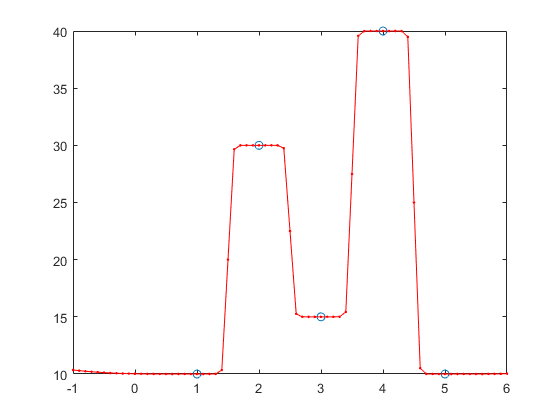

intpol_IDW([1 2 3 4 5],[10 30 15 40 10],[-1:0.1:6], 10);

**Úkol 6.**  Pročtení pasáží v knize, studování a přepisování poznámek a příkladů mi zabralo asi 8h, z části asi také proto, že jsem si stále ještě osahával MATLAB.

 *“In theory, there’s no difference between theory and practice. In practice, there is.”  Walter Savitch*